# Modified Denavit-Hartenberg Parameters 

Building on the coordinate system transformations script, we will take what we have learned and apply it to another approach for describing the motion of a manipulator. This approach refers to using Modified Denavit-Hartenberg (DH) parameters. At the end of this script, we will investigate a simulated robot manipulator built using DH parameters.

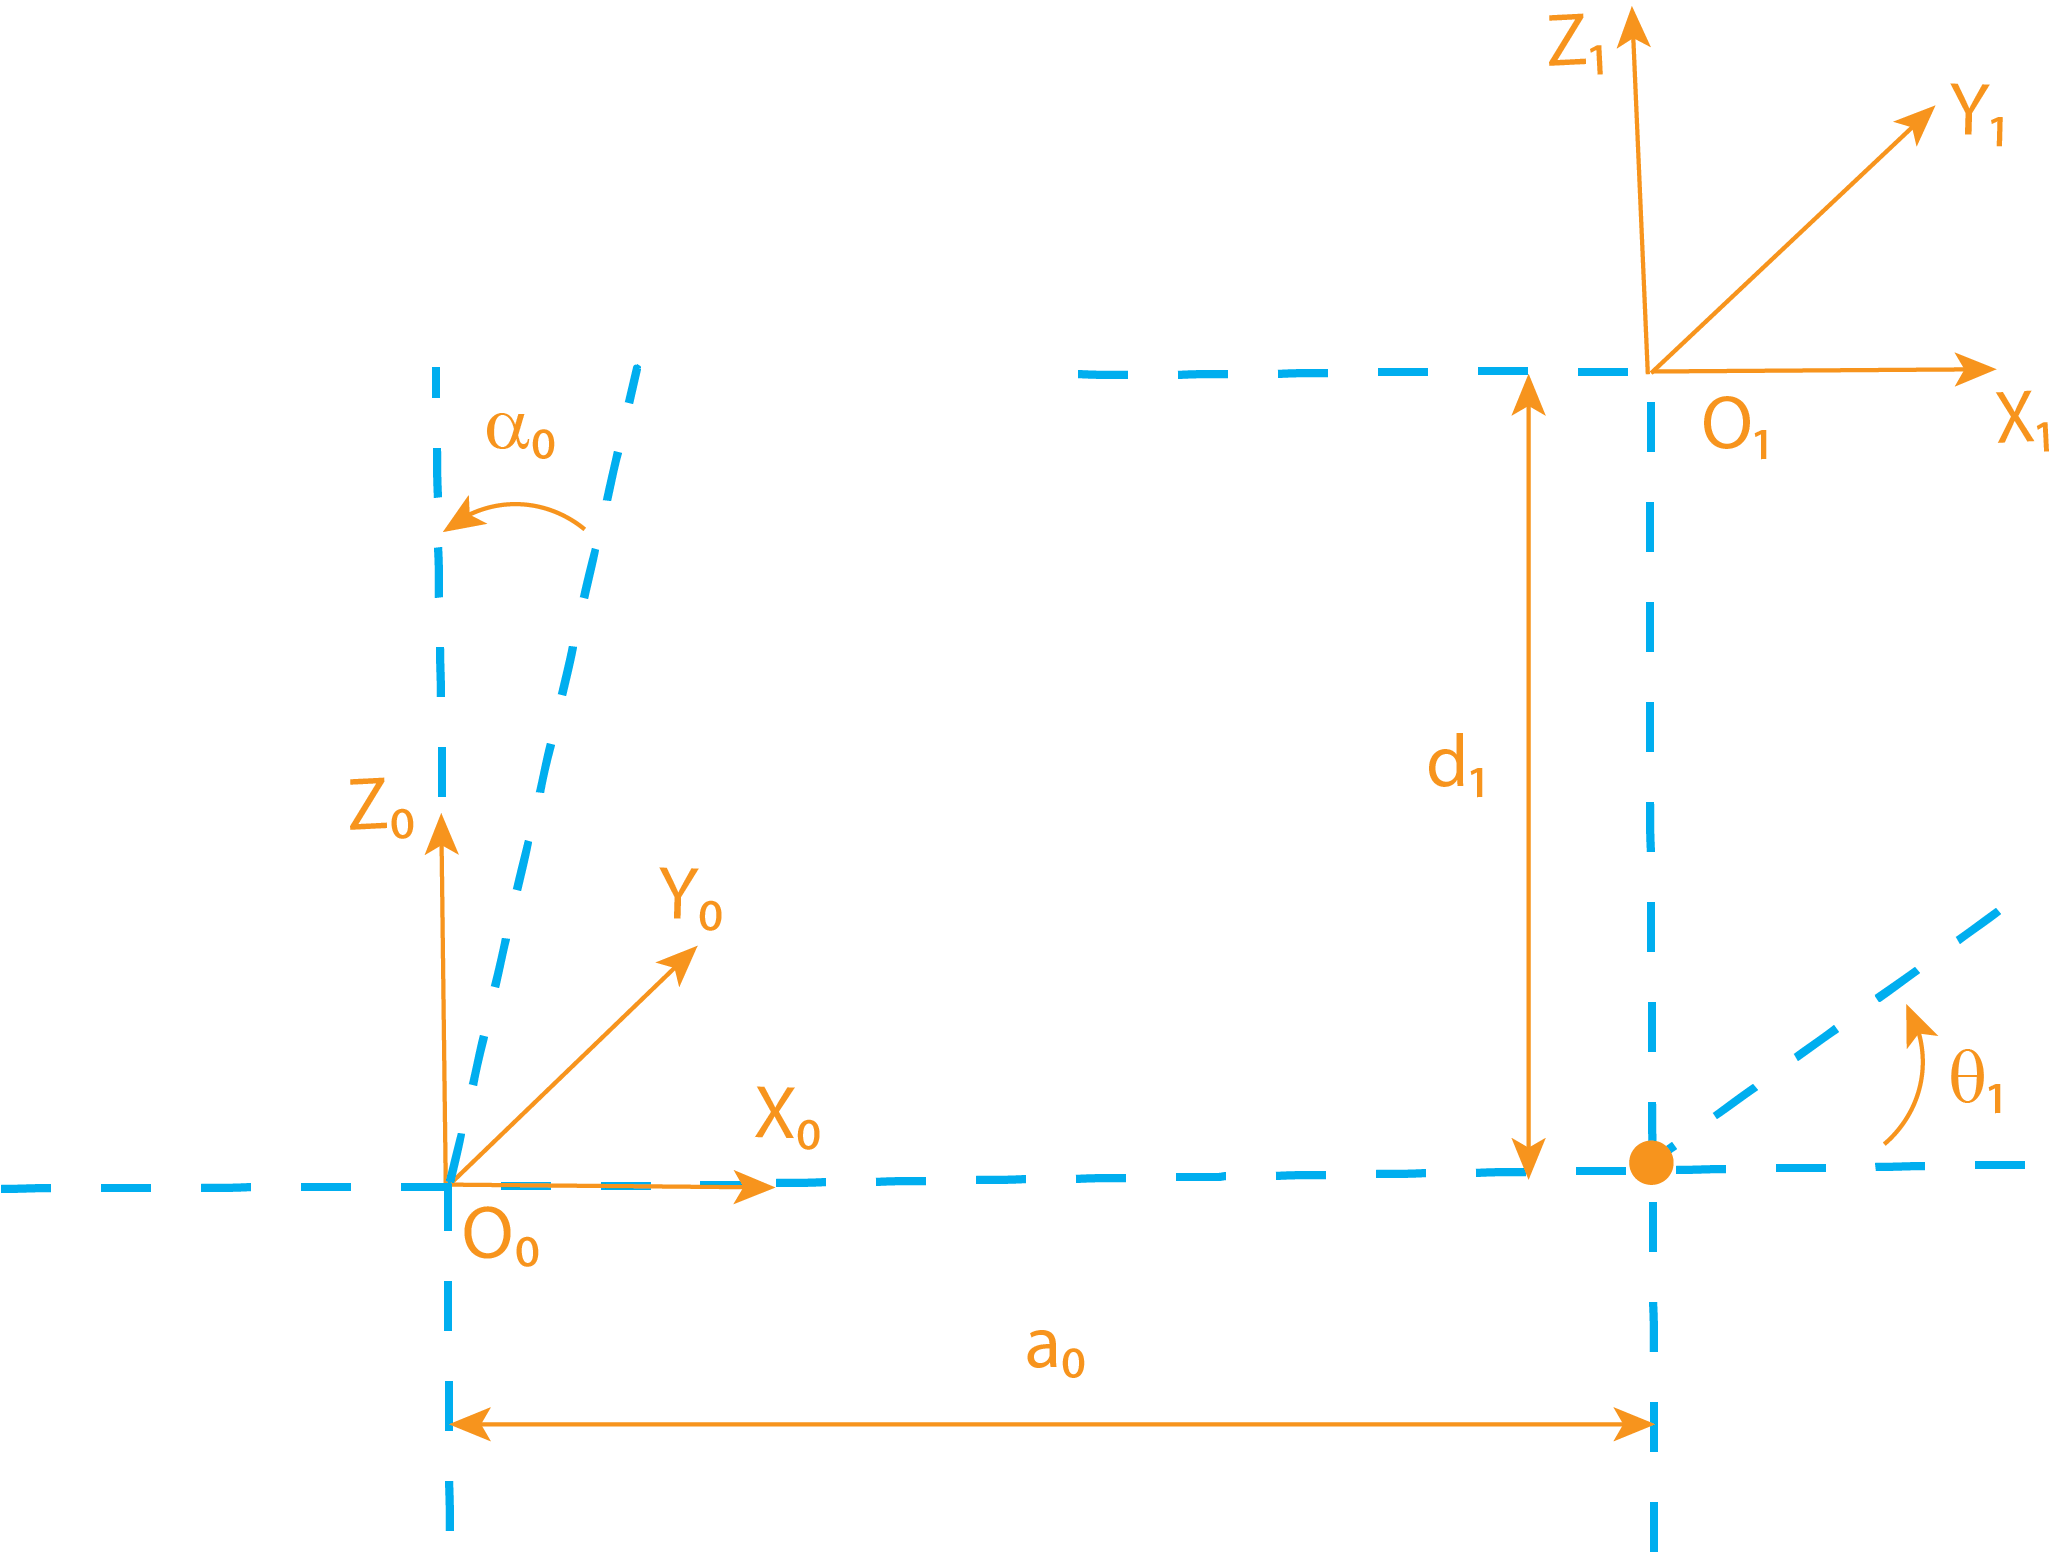

Building a robot model with modified DH parameters and built-in MATLAB functions.

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

## Modified DH Parameters

We have just learned how transformation matrices can help transform from any cartesian coordinate system to any other cartesian coordinate system if we can specify the translation and rotation matrices. We created the transformation matrix using translation and rotation matrices. We will now perform the same task using DH parameters. DH parameters offer a convenient, widely used notation to specify these transformations for industrial robots. A visualization of how modified DH parameters are determined is shown below:

  **Pro-tip**. The origins of the coordinate systems, $O_0 \;\textrm{and}\;O_1$, are shown in the figure below. Imagine each origin as the intersection between robot links, or joints.

The modified DH parameters are derived from the common normal line ($a$) between the two x-axes. Where [1]:

- $a$ - Link Length — The distance from the z-axis {0} to z-axis {1} measured along x-axis {0}

- $\alpha$ - Link Twist — The angle between the z-axis {0} to z-axis {1} measured along x-axis {0}

- $d$ - Link Offset — The distance from the x-axis {0} to x-axis {1} measured along z-axis {1}

- $\theta$ - Joint angle — The angle between the x-axis {0} to x-axis {1} measured along z-axis {1}

### Parameter Definitions

First, let's look at how transformation matrices can transform between two different coordinate systems using these parameters. The assumption in modified DH parameters is that any coordinate system for an industrial manipulator can be represented using just 4 operations in the following sequence:

- Rotation of angle $\alpha$ about the x-axis

- Translation of distance $a$ along the x-axis

- Rotation of angle $\theta$ about the z-axis

- Translation of distance $d$ along the z-axis

This can be translated to a governing equation for creating the transformation matrix as:

#### 
$$T_i^{i-1} ={\textrm{Rot}}_{x_{i-1} } \left(\alpha_{i-1} \right)\cdot {\textrm{Trans}}_{x_{i-1} } \left(a_{i-1} \right)\;\cdot {\textrm{Rot}}_{z_i } \;{\left(\theta_i \right)\cdot {\textrm{Trans}}_{z_i } }_{\;} \left(d_i \right)$$


and,

#### 
$$T_i^{i-1} =\left\lbrack \begin{array}{cccc}
\cos \left(\theta_i \right) & -\sin \left(\theta_i \right) & 0 & a_{i-1} \\
\sin \left(\theta_i \right)\cdot \cos \left(\alpha_{i-1} \right) & \cos \left(\theta_i \right)\cdot \cos \left(\alpha_{i-1} \right) & -\sin \left(\alpha_{i-1} \right) & -\sin \left(\alpha_{i-1} \right)\cdot d_i \\
\sin \left(\theta_i \right)\cdot \sin \left(\alpha_{i-1} \right) & \cos \left(\theta_i \right)\cdot \sin \left(\alpha_{i-1} \right) & \cos \left(\alpha_{i-1} \right) & \cos \left(\alpha_{i-1} \right)\cdot d_i \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


For the four DH parameters, two describe the link (*θ,d*) and the other two describe the link's connection to an adjacent link (*a*,*α*). In the most common cases, three of the parameters will be fixed. The remaining one will represent motion according to the joint type: 

- $\theta$ if the joint is revolute (One DOF Rotational)

- $d$ if the joint is prismatic (One DOF Translational)

### Transformation Matrix using DH Parameters

Traditionally, we would assign the link parameters by following the DH convention procedure based on the robot links and the defined axes*. *In this section, we will skip the assignment and create a sample set of DH parameters for a three degree of freedom (3DOF) robot that only has revolute joints. We will explore how transformation matrices can be created using DH parameters.

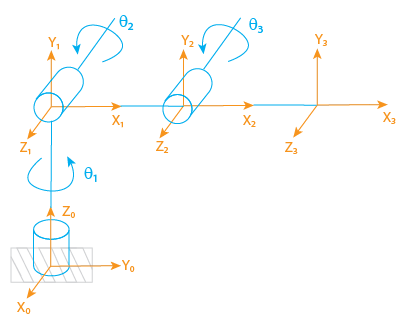

From the figure above, for a 3DOF robot, here is a sample set of DH parameters:

#### 
$$\textrm{DH}=\left\lbrack \begin{array}{cccc}
a & \alpha  & d & \theta \\
0 & 90 & 2 & 0\\
1 & 0 & 0 & 90\\
1 & 0 & 0 & 90
\end{array}\right\rbrack$$


  **Pro-tip**.To learn how to assign parameters based on DH convention, you can check out the first two links in the Further Exploration section.

% Definition of the link lengths and joint angles in DH Parameter Convention
a1 = 0;  alpha1 = 90;  d1 = 2;  th1 = 0;   % Joint 1
a2 = 1;  alpha2 = 0;   d2 = 0;  th2 = 90;  % Joint 2
a3 = 1;  alpha3 = 0;   d3 = 0;  th3 = 90;  % Joint 3

% Compute the DH parameters and display
tFlag = false;
if tFlag
    a = [a1;a2;a3];
    alpha = [alpha1;alpha2;alpha3];
    d = [d1;d2;d3];
    theta = [th1;th2;th3];
    DH = table(a,alpha,d,theta)
end

From the previous script, we can connect multiple frames in the following way for a three-joint robot:

#### 
$$T_0^3 =T_0^1 \;T_1^2 \;T_2^3$$


% Generation of Transformation Matrices based on DH Parameters
if tFlag
    T01 = moddh_param(a1,alpha1,d1,th1);
    T12 = moddh_param(a2,alpha2,d2,th2);
    T23 = moddh_param(a3,alpha3,d3,th3);

    T03 = T01*T12*T23
end

Let's look at the figure above as a diagram of a manipulator. Frame {0} can be considered the base of the manipulator and frame {3} could be considered the end-effector. If point $p_0$ is in the base frame {0}, we can get its position with respect to the reference frame of the end-effector {3} by:

#### 
$$p_3 =T_0^3 \cdot p_0$$


% Load parameters from coorindate system transformations script
if tFlag
    load Data/DH_Exercise.mat

    % 4x3 Multi-point p Matrix
    p0 = pM;

    % Forward Transformation
    p3 = T03*p0
end

To verify this works, we can calculate the inverse as:

#### 
$$p_0 =p_3 \cdot {\left(T_0^3 \right)}^{-1}$$

$$\Rightarrow$$

$${\left(T_0^3 \right)}^{-1} =T_3^0$$


if tFlag
    % Inverse Transformation
    T30 = inv(T03);

    % Inverse transform check
    p_0 = T30*p3 %#ok<MINV> 
end

  **Try**. Use DH parameters to transform a robotic joint to the reference frame {3} from the base frame {0}.

% Animate forward/inverse DH Parameter transformation matrices
dhFlag = false;

% Plot Points for p1
g1 = plot3(p0(1,1),p0(2,1),p0(3,1));
g1.Color = "green";
g1.Marker = "*";
text(p0(1,1),p0(2,1),p0(3,1),'  p*');

hold on
 
% Axes setting for coordinate frames
ax5 = gca;
quiverSize = max([range(ax5.XLim) range(ax5.YLim) range(ax5.ZLim)]*2); 

% Add coordinate frames to non-transformed point   
qdh1 = quiver3(p0(1), p0(2), p0(3), nT1(1), nT1(2), nT1(3), quiverSize ,'SeriesIndex', 1, 'LineWidth',1.5);
qdh2 = quiver3(p0(1), p0(2), p0(3), nT2(1), nT2(2), nT2(3), quiverSize ,'SeriesIndex', 2, 'LineWidth',1.5);
qdh3 = quiver3(p0(1), p0(2), p0(3), nT3(1), nT3(2), nT3(3), quiverSize ,'SeriesIndex', 3, 'LineWidth',1.5);

% Package figure objects
FigDH = [g1;qdh1;qdh2;qdh3];

% Assign names to axes and create legend
g1.Parent.XLabel.String = "X (m)";
g1.Parent.YLabel.String = "Y (m)";
g1.Parent.ZLabel.String = "Z (m)";
% Adjust limits to fit all point transforms
g1.Parent.XLim = [min(min([p0 p3]))-5 max(max([p0 p3]))+5];
g1.Parent.YLim = [min(min([p0 p3]))-5 max(max([p0 p3]))+5];
g1.Parent.ZLim = [min(min([p0 p3]))-5 max(max([p0 p3]))+5];
legend(ax5,{'','X','Y','Z'});
grid

% Animate transformation of points
if dhFlag 
    animatePlotComb(FigDH,p0,p3,p_0,nT1,nT2,nT3,T1,T2,T3);
end

### DH Parameters Conclusion 

This example shows that we can transform any point from the base frame into the reference frame (e.g., the end-effector) of any joint of the robot and back, using DH parameters. Moving forward, we can apply these parameters to a real robot and modify them by combining all of this into a single MATLAB function and then change the values of the robot joints to see how the position changes.

## Build Robot Using DH Parameters and Built-in Functions

The same Denavit-Hartenberg (DH) parameters we use to build a robot manually can also be passed to built-in MATLAB® functions. You can specify the relative DH parameters for each joint as you attach them. Leveraging other built-in robotics functions has advantages, including:

- Visualize and interact with the robot model

- Perform inverse kinematics 

- Trajectory Generation and Following

- Perform Manipulator Motion Planning

- Use Collision Detection to ensure safe and effective motion for your robot

** Demonstration**. We will build a robot using its DH parameters and built-in MATLAB functions. 

First, let's specify the DH parameters for a 6DOF Puma 560 [2] robot as a matrix. For this example, $a$ and $d$ are expressed in meters while $\alpha$ and $\theta$ are expressed in degrees:

#### 
$$\textrm{Puma560}\;=\left\lbrack \begin{array}{cccc}
a & \alpha  & d & \theta \\
0 & 90 & 0 & 270\\
0\ldotp 4318 & 0 & 0 & 90\\
0\ldotp 0203 & -90 & 0\ldotp 15005 & 0\\
0 & 90 & 0\ldotp 4318 & 0\\
0 & -90 & 0 & 0\\
0 & 0 & 0 & 0
\end{array}\right\rbrack$$


% DH parameters of Puma 560 robot. Units are in degrees for ease of reading
% but will be converted to radians for trigonometric calculations
Puma560 = [0   	    pi/2	    0        270;
           0.4318	0           0        90;
           0.0203	-pi/2	    0.15005	 0;
           0   	    pi/2	    0.4318	 0;
           0        -pi/2	    0   	 0;
           0        0           0        0];

rFlag = false;

### Create Rigid Body Elements

 Begin with creating a [`rigidBodyTree`](https://www.mathworks.com/help/robotics/ref/rigidbodytree.html) robot model in MATLAB. When creating a `rigidBodyTree `model, the base of the robot is automatically generated as your first rigid body. The base of the robot is a fixed frame that defines the world coordinate system.

if rFlag
    % Create stored variable for rigidBodyTree object
    robot = rigidBodyTree;
    robot.DataFormat = 'column';
    
    display(robot)
end

Next, we will create a series of [`rigidBody`](https://www.mathworks.com/help/robotics/ref/rigidbody.html) objects. These will define solid bodies of the robot that cannot deform. This robot consists of a rotating base, 4 links, and an end-effector.

if rFlag
    % Define bodies of the robot
    rotatingBase = rigidBody("rotatingBase");
    link1 = rigidBody("Link1");
    link2 = rigidBody("Link2");
    link3 = rigidBody("Link3");
    link4 = rigidBody("Link4");
    endeff = rigidBody("endEffector");
    
    display(rotatingBase)
end

### Create and Attach Joints to Rigid Body Elements

Each rigid body is attached to one another using a joint. This robot has six revolute joints. Create a series of [`rigidBodyJoint`](https://www.mathworks.com/help/robotics/ref/rigidbodyjoint.html) objects for each rigid body.

if rFlag
    % Define joints of the robot
    jntBase = rigidBodyJoint("jntBase","revolute");
    jnt1 = rigidBodyJoint("jnt1","revolute");
    jnt2 = rigidBodyJoint("jnt2","revolute");
    jnt3 = rigidBodyJoint("jnt3","revolute");
    jnt4 = rigidBodyJoint("jnt4","revolute");
    jntEndEffector = rigidBodyJoint("jntEndEffector","revolute");
    
    display(jntBase)
end

### Assemble Robot

Finally, we will visualize the process of assembling the frames of the Puma 560 robot. To set the defined DH parameters to the joints of the robot (the body-to-body transformations), the [`setFixedTransform`](https://www.mathworks.com/help/robotics/ref/rigidbodyjoint.setfixedtransform.html) command is used. Once the joint objects are added to the rigid body objects, the fully defined body object can be attached to the robot's rigid body tree. The function ignores the final element of the DH parameters, theta, because the angle of the body is dependent on the joint position. Hence, why the values were set to zero in the matrix above. To change the theta parameters, adding a configuration of joint angles to the [`show`](https://www.mathworks.com/help/robotics/ref/rigidbodytree.show.html?searchHighlight=show%20robot&s_tid=srchtitle_show%20robot_1) command provides a change in orientation and position of the robot.

 

% Place bodies and joints into a cell array
bodies = {rotatingBase,link1,link2,link3,link4,endeff};
joints = {jntBase,jnt1,jnt2,jnt3,jnt4,jntEndEffector};

% Robot Configuration for joint angles
angles = [270;90;0;0;0;0];
config = angles*pi/180;

% Assign bodies/DH parameters to robot, draw on a figure, label axes and adjust figure size 
rFig = figure;
for i = 1:length(bodies)
    setFixedTransform(joints{i},Puma560(i,:),"dh");
    bodies{i}.Joint = joints{i};
    if i == 1 % Add first body to base
        addBody(robot,bodies{i},"base")
    else % Add current body to previous body by name
        addBody(robot,bodies{i},bodies{i-1}.Name)
    end
end
    drawnow    
    show(robot,config,'Frames','on','Visuals','on');
    xlabel('X (m)')
    ylabel('Y (m)')
    zlabel('Z (m)')
    title('Assemble PUMA 560 Robot');
    view([145 18]);
    set(rFig,'units','normalized','outerposition',[0 0 1 1]);
    set(rFig,'WindowState','minimized');

Upon building the robot, the changes to the rigidBodyTree object can be observed.

% Display the updated robot structure
display(robot)

Verify that your robot has been built properly by using the [`showdetails`](https://www.mathworks.com/help/robotics/ref/rigidbodytree.showdetails.html)` command`. This lists all the bodies/joints of the robot along with their parent-child relationships. 

% Display the details of the robot
showdetails(robot)

   **Pro-tip**. You may notice that there is no physical structure for the robot, just a frame representation. This is because no collision objects were created. Collision objects represent the shapes and dimensions of each rigid body. To add geometric representation to your rigid bodies, you can use the [`addCollision`](https://www.mathworks.com/help/robotics/ref/rigidbody.addcollision.html) command. 

### Interact with Robot Model

Visualizing the robot model can be helpful in making sure you built the correct robot. However, interacting with the robot model can be helpful in making sure the robot works as intended. To change the robot configuration interactively instead of programmatically, create an [`interactiveRigidBodyTree`](https://www.mathworks.com/help/robotics/ref/interactiverigidbodytree.html) object. This type of object allows the user to add various joint configurations, constraints, and generate trajectories for the robot model. A yellow marker for user-input movement will be placed on the end-effector by default. By right-clicking a specific coordinate frame and selecting the option *"Set body as marker body"*, you can change the marker to another coordinate frame other than the end-effector. In the figure that pops up, left-click and drag the yellow marker in the interactive GUI to reposition the end-effector or other joints in the model. 

Observe that while we defined this PUMA 560 robot to have 6DOF, visually you are only seeing 4DOF in the figure. There are indeed 6DOF. Counting all the coordinate frames in the figure except for the one at the end-effector, you have 3DOF. The remaining 3DOF are all apart of the end-effector rotating about the X,Y, and Z axes. At the moment, the joints at the end-effector are overlapping (based on current joint angles), which is why you only see roughly one body frame at the end-effector. You may be wondering why there are so many joints in the end-effector if you only need one joint there to realistically accomplish a task. This is because we want the maximum amount of flexibility in the end-effector to achieve it's goal. By interacting with this robot as described above, you will be able to see the other "hidden" body frames.

 

% Create an interaction with the robot that controls joint movement
intRobot = interactiveRigidBodyTree(robot,'Frames','on',MarkerScaleFactor=0.5);
showFigure(intRobot);
intRobot.Configuration = angles*pi/180;
intRobot.MarkerControlMethod =  'JointControl';
xlabel('X (m)')
ylabel('Y (m)')
zlabel('Z (m)')
title('Interact with PUMA 560 Robot');
view([145 18]);    
set(gcf,'units','normalized','outerposition',[0 0 1 1]);

  **Try**. Select **Output Inline **using the icon   at the top right of the Live Editor pane to show the code. Navigate to line 124 and change the joint angles to [270;0;70;-45;45;-15]. Now rerun the script and try to interact with the robot model. This way, it will be easier to observe all 6DOF and their associated coordinate frames.

  **Pro-tip**. To interact with more detailed models provided with [Robotics System Toolbox™](https://www.mathworks.com/products/robotics.html), see [Load Predefined Robot Models](https://www.mathworks.com/help/robotics/ug/load-predefined-robot-models.html). To load a robot model from a set of common commercially available robots, use the [`loadrobot`](https://www.mathworks.com/help/robotics/ref/loadrobot.html) function. If you have a [URDF](https://www.mathworks.com/help/sm/ug/urdf-import.html) file or [Simscape Multibody™](https://www.mathworks.com/products/simscape-multibody.html) model of your robot, you can import it using [`importrobot`](https://www.mathworks.com/help/robotics/ref/importrobot.html). Both methods will bring the robot into MATLAB as a rigidBodyTree object.

## Next Steps

We have now applied our learnings of coordinate frame transformations to DH parameters; a simpler way of defining a robot's position. Let us now move to the next stage and start exploring the fundamentals of forward and inverse kinematics with DH parameters before applying them to solve practical problems.

## Definitions

Modified DH Parameters - Four parameters associated with a particular convention for attaching reference frames to the links of a spatial kinematic chain, or robot manipulator. The convention of the reference frames follows $O_{i-1}$ and $O_i$. (↑ Return to Text)

Degrees of Freedom (DOF) - The number of independent variables that define the possible positions or motions of a mechanical system in space.  (↑ Return to Text)

## Further Exploration

- [Build Manipulator Robot Using Kinematic DH Parameters](https://www.mathworks.com/help/robotics/ug/build-manipulator-robot-using-kinematic-dh-parameters.html)

- [DQ Parameters](https://github.com/dqrobotics/learning-dqrobotics-in-matlab/tree/master/robotic_manipulators)

- [Robotics Playground Toolbox](https://www.mathworks.com/matlabcentral/fileexchange/67157-robotics-playground)

## References

[1] Craig. (2022). 3.4 CONVENTION FOR AFFIXING FRAMES TO LINKS. In *Introduction to robotics: Mechanics and control* (p. 69). essay, Pearson Education Limited. (↑ Return to Text)

[2] P. I. Corke and B. Armstrong-Helouvry, "A search for consensus among model parameters reported for the PUMA 560 robot," *Proceedings of the 1994 IEEE International Conference on Robotics and Automation*, San Diego, CA, USA, 1994, pp. 1608-1613 vol.2, doi: 10.1109/ROBOT.1994.351360. (↑ Return to Text)

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function T = moddh_param(a,alpha,d,theta)
    % This function generates a transformation matrix T depending on input 
    % dh parameters: theta, d, alpha and a
    arguments
        a (1,1) double {mustBeNumeric}
        alpha (1,1) double {mustBeNumeric}
        d (1,1) double {mustBeNumeric}
        theta (1,1) double {mustBeNumeric}     
    end

    % Calculating sin-cos for theta and alpha (Converts Deg to Rad before
    % calculation
    St = sin(deg2rad(theta));
    Ct = cos(deg2rad(theta));

    Sa = sin(deg2rad(alpha));
    Ca = cos(deg2rad(alpha));

    % Calculate matrix T
    T = [Ct    -St     0   a;...
         St*Ca Ct*Ca  -Sa -Sa*d;...
         St*Sa Ct*Sa   Ca  Ca*d;...
         0     0       0   1  ];
end

function animatePlotComb(Obj,pM1,pM2,pM3,nT1,nT2,nT3,T1,T2,T3)
    % This function animates a 3D plot specifically setup for
    % combining transformations of points and their coordinate frames in space

    % Creating a time span for animation
    tspan = linspace(0, 2*pi, 300);

    % Number of points to animate
    n = length(tspan)/2;

    % Point Path (From original points to transformed points)
    tr1 = arrayfun(@(x,y) linspace(x,y,n),pM1,pM2,'UniformOutput',false);

    % Coordinate System Path (from original coordinate system to transformed coordinate system)
    csT1 = arrayfun(@(x,y) linspace(x,y,n),nT1,T1,'UniformOutput',false);
    csT2 = arrayfun(@(x,y) linspace(x,y,n),nT2,T2,'UniformOutput',false);
    csT3 = arrayfun(@(x,y) linspace(x,y,n),nT3,T3,'UniformOutput',false);

    % Point Path (From transformed points to original points)
    tr1i = arrayfun(@(x,y) linspace(x,y,n),pM2,pM3,'UniformOutput',false);

    % Coordinate System Path (from transformed coordinate system to original coordinate system)
    csT1i = arrayfun(@(x,y) linspace(x,y,n),T1,nT1,'UniformOutput',false);
    csT2i = arrayfun(@(x,y) linspace(x,y,n),T2,nT2,'UniformOutput',false);
    csT3i = arrayfun(@(x,y) linspace(x,y,n),T3,nT3,'UniformOutput',false);

    % Animation of plot
    % Updates the X,Y,Z values of each figure object per time step i.
    for i=1:length(tspan)
        % Forward Transformation
        if i <= n 
          % Transforms point p* location in 3D space  
          Obj(1).XData = tr1{1}(i);  
          Obj(1).YData = tr1{2}(i);  
          Obj(1).ZData = tr1{3}(i);
          Obj(1).Parent.Children(4).Position = [tr1{1}(i);tr1{2}(i);tr1{3}(i)];
          
          % Plots coordinate frame location in 3D space as point moves
          Obj(2).XData = tr1{1}(i); Obj(3).XData = tr1{1}(i); Obj(4).XData = tr1{1}(i);
          Obj(2).YData = tr1{2}(i); Obj(3).YData = tr1{2}(i); Obj(4).YData = tr1{2}(i);
          Obj(2).ZData = tr1{3}(i); Obj(3).ZData = tr1{3}(i); Obj(4).ZData = tr1{3}(i);

          % Transforms coordinate frame location in 3D space as point moves
          Obj(2).UData = csT1{1}(i); Obj(3).UData = csT2{1}(i); Obj(4).UData = csT3{1}(i);
          Obj(2).VData = csT1{2}(i); Obj(3).VData = csT2{2}(i); Obj(4).VData = csT3{2}(i);
          Obj(2).WData = csT1{3}(i); Obj(3).WData = csT2{3}(i); Obj(4).WData = csT3{3}(i);
        % Inverse Transformation  
        elseif i > n          
          % Transforms point p* location in 3D space  
          Obj(1).XData = tr1i{1}(i-n);  
          Obj(1).YData = tr1i{2}(i-n);  
          Obj(1).ZData = tr1i{3}(i-n);
          Obj(1).Parent.Children(4).Position = [tr1i{1}(i-n);tr1i{2}(i-n);tr1i{3}(i-n)];
          
          % Plots coordinate frame location in 3D space as point moves
          Obj(2).XData = tr1i{1}(i-n); Obj(3).XData = tr1i{1}(i-n); Obj(4).XData = tr1i{1}(i-n);
          Obj(2).YData = tr1i{2}(i-n); Obj(3).YData = tr1i{2}(i-n); Obj(4).YData = tr1i{2}(i-n);
          Obj(2).ZData = tr1i{3}(i-n); Obj(3).ZData = tr1i{3}(i-n); Obj(4).ZData = tr1i{3}(i-n);

          % Transforms coordinate frame location in 3D space as point moves
          Obj(2).UData = csT1i{1}(i-n); Obj(3).UData = csT2i{1}(i-n); Obj(4).UData = csT3i{1}(i-n);
          Obj(2).VData = csT1i{2}(i-n); Obj(3).VData = csT2i{2}(i-n); Obj(4).VData = csT3i{2}(i-n);
          Obj(2).WData = csT1i{3}(i-n); Obj(3).WData = csT2i{3}(i-n); Obj(4).WData = csT3i{3}(i-n);
        end
        % Plot title
        title({'Forward/Inverse Transformation', 'of Point using DH Parameters', ['(t = ' num2str(tspan(i)) ')']})
        drawnow
    end
end